## Cross-platform validation: Dynasim vs Brian2

addpath(genpath('/Users/teatompos/Documents/GitHub/PhD_Project1--small-spiking-neural-network'))
addpath(genpath('/Users/teatompos/Desktop/Matlab_scripts/RU_1st_internship_Neurophysiology_Dept/DynaSim'))
clear all; close all; 

defaultCellSize_um2 = 1500; % um2
defaultCellSize_cm2 = defaultCellSize_um2 * (100*100)/(1000*1000*1000*1000); % cm2

%%% STEP CURRENT AMPLITUDE
effective_amplitudes = [0 10 20 30 50 80 120 200]; % pA

%%% RELATIVE CURRENT (effective amplitude is in pA, but Dynasim takes in uA/cm2) 
stimAmps = (effective_amplitudes*1e-6)./defaultCellSize_cm2; % [uA/cm2]
% stimAmps = [0 0.1 0.2 0.3 0.32 0.35 0.4]; % [uA/cm2]

% Define equations of cell model (same for all populations)
eqns={
  'dV/dt=@current';
};

time_end = 500; % in milliseconds
numcells = 1;

TC.populations(1).name='TC';
TC.populations(1).size=numcells;
TC.populations(1).equations=eqns;
TC.populations(1).mechanism_list={'iNaChing2010TC','iKChing2010TC',...
                                    'CaBufferChing2010TC','iTChing2010TC',...
                                    'iHChing2010TC','iLeakChing2010TC',...
                                    'iKLeakChing2010TC',...
                                    'stim'};
TC.populations(1).parameters={'gH',0.01, 'onset', 200, 'offset', 250};

Ching2010 = dsSimulate(TC,'vary',{'TC','stim_amp',stimAmps},...
                  'random_seed',1,...
                  'tspan',[0 time_end],'solver','rk4');

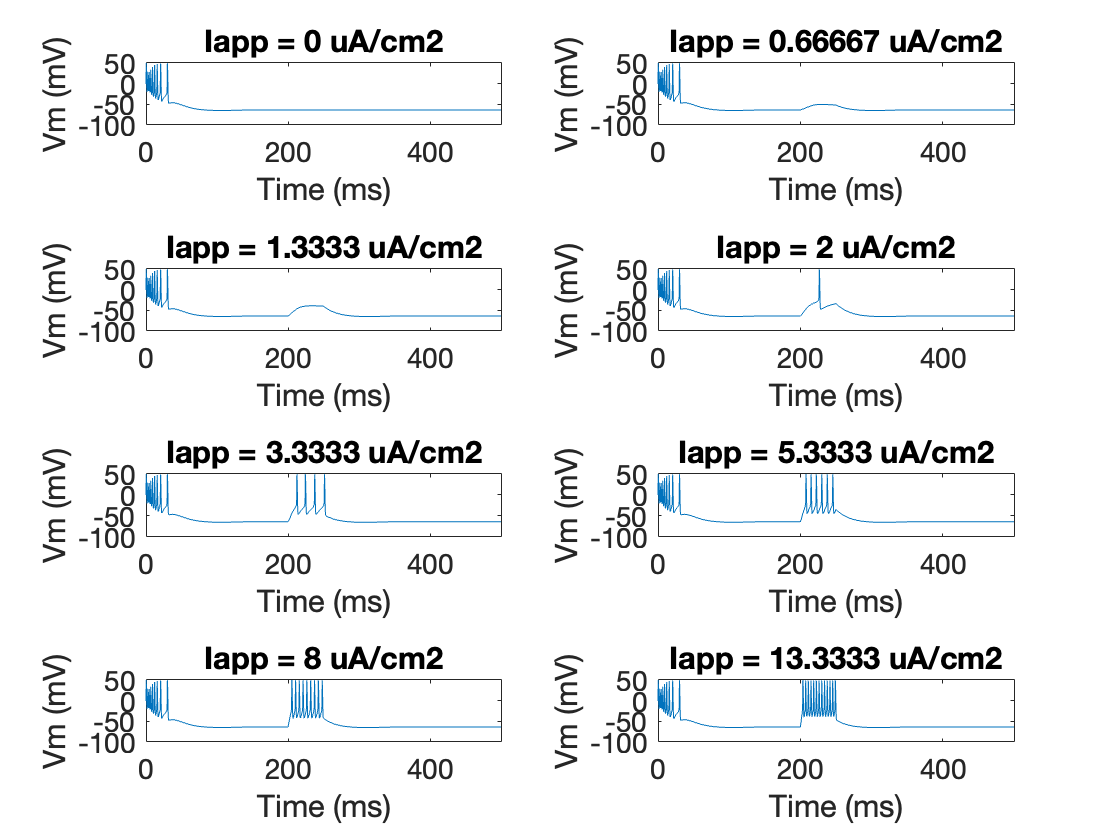


%%% PLOT RESULTS
currents = unique(cell2mat({Ching2010.TC_stim_amp}'));

figure; clf; tiledlayout(4,2)

for cur = 1:length(currents)
    nexttile;
    cur_val = currents(cur);

    idx = find([Ching2010.TC_stim_amp]==cur_val);

    plot(Ching2010(idx).time, Ching2010(idx).TC_V)
    xlabel('Time (ms)')
    ylabel('Vm (mV)')
    ylim([-100 50])
    xlim([Ching2010(idx).time(1) Ching2010(idx).time(end)])
    set(gca,'fontsize', 14)
    t = ['Iapp = ' num2str(cur_val) ' uA/cm2'];
    title(t,'interpreter','none')
end